## A MATLAB Live Script  for MA378 comparing linear, natural cubic, and PCHIP interpolation

Picewise polynomial interpolation examples. 

NOTE: The version of "pchip" used here is not the same as in class: it doesn't use $f'(x)$and so is less accurate. But it is still monotone.

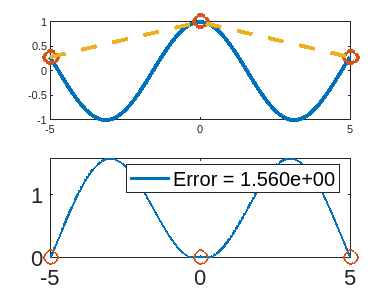

a=-5; b=5;
f = @(x)cos(x);
n=2;
xp = linspace(a,b,n+1);
l = @(x)interp1(xp, f(xp), x);
X = linspace(a,b,1001);
Diff = abs(f(X)-l(X));
Error = max(Diff);
subplot(2,1,1);  plot(X, f(X), xp, f(xp), 'o', X, l(X), '--', 'LineWidth',3, 'MarkerSize',10);
subplot(2,1,2);  plot(X, Diff, '-', xp, xp*0, 'o', 'LineWidth', 2, 'MarkerSize',10);
legend(sprintf("Error = %8.3e", Error));
set(gca,'FontSize', 17)